a = 0;
b = 0;
c = 1;
d = 0;
e = 4;
f = 0;
B = [a b/2; b/2 c]

B =      0     0
     0     1


[e_vec,e_num] = eig(B)

e_vec =      1     0
     0     1


e_num =      0     0
     0     1



if e_num(1,1)>0 && e_num(2,2)>0 
    text = "Эллипс"
    k=0
end
if (e_num(1,1)>0 && e_num(2,2)<0) || (e_num(1,1)<0 && e_num(2,2)>0)
    text = "Гипербола"
    k = 0
end
if (e_num(1,1)==0 && e_num(2,2)~=0) || (e_num(1,1)~=0 && e_num(2,2)==0)
    if (a==0 && b==0 && c~=0 && d==0 && (f~=0 || e~=0)) || (a~=0 && b==0 && c==0 && e==0 && (f~=0 || d~=0))
        text = "Пара пересекающихся прямых"
        k=2;
    else
    text = "Парабола"
    k = 1
    end
end

text = "Пара пересекающихся прямых"


syms x y x1 y1 x2 y2 xf yf x3 y3 xt yt t

X1Y1=[x1;y1]

$$X1Y1 = \left(\begin{array}{c} x_{1}\\ y_{1} \end{array}\right)$$

XY = e_vec*X1Y1

$$XY = \left(\begin{array}{c} x_{1}\\ y_{1} \end{array}\right)$$

x = XY(1)

$$x = x_{1}$$

y = XY(2)

$$y = y_{1}$$

f_original = a*xf^2 +b*xf*yf + c*yf^2 +d*xf + e*yf + f

$$f\_original = {\mathrm{yf}}^{2}+4\,\mathrm{yf}$$

f_first = a*x^2 +b*x*y + c*y^2 +d*x + e*y + f

$$f\_first = {y_{1}}^{2}+4\,y_{1}$$

f_new = simplify(f_first)

$$f\_new = y_{1}\,\left(y_{1}+4\right)$$

orig = fimplicit(f_original, [-10 10 -10 10])

orig =   ImplicitFunctionLine with properties:

     Function: [1×1 sym]
       XRange: [-10 10]
       YRange: [-10 10]
        Color: [0 0.4470 0.7410]
    LineStyle: '-'
    LineWidth: 0.5000

  Show all properties



hold on
cxy = coeffs(f_new, [x1 y1])

$$cxy = \left(\begin{array}{cc} 4 & 1 \end{array}\right)$$

if (k==2)
    
if (length(cxy)==2)
     if a==0 && f~=0
       f_2 = (y3^2)/(cxy(1)/cxy(2))
       f_3 = 1
       xC = x3
       yC = y3
     end
     if a==0 && f==0
       f_2 = (y3+cxy(1)/(2*cxy(2)))^2
       f_3 = 0
       xC = x3+cxy(1)/(2*cxy(2))
       yC = y3
     end
     if c==0 && f~=0
       f_2 = -(x3^2)/(cxy(1)/cxy(2))
       f_3 = 1
       xC = x3
       yC = y3
     end
     if c==0 && f==0
       f_2 = (x3+cxy(1)/(2*cxy(2)))^2
       f_3 = 0
       xC = x3+cxy(1)/(2*cxy(2))
       yC = y3
     end
if (length(cxy)==3)
    if a == 0
    f_2=(y3 + cxy(2)/(2*cxy(3)))^2/((cxy(2)/(2*cxy(3)))^2 - cxy(1)/cxy(3))
    f_3 = 1
    xC = (x3 + cxy(2)/(2*cxy(3)))
    yC = y3
    
    end
    if c == 0
    f_2=(x3 + cxy(2)/(2*cxy(3)))^2/((cxy(2)/(2*cxy(3)))^2 - cxy(1)/cxy(3))
    f_3 = 1
    xC = (x3 + cxy(2)/(2*cxy(3)))
    yC = y3
    end
end  
end
end

$$f\_2 = {\left(y_{3}+2\right)}^{2}$$

f_3 = 0

$$xC = x_{3}+2$$

$$yC = y_{3}$$

 D = solve([xC==0,yC ==0 ],x3,y3)

D = struct with fields:
    x3: [1×1 sym]
    y3: [1×1 sym]


    R = [D.x3, D.y3]

$$R = \left(\begin{array}{cc} -2 & 0 \end{array}\right)$$

    plot(D.x3,D.y3, "ro")
    line([D.x3 D.x3+10*e_vec(1,1)], [D.y3 D.y3+10*e_vec(2,1)], "color", "r")
    line([D.x3 D.x3-10*e_vec(1,1)], [D.y3 D.y3-10*e_vec(2,1)], "color", "r")
    line([D.x3 D.x3+10*e_vec(1,2)], [D.y3 D.y3+10*e_vec(2,2)], "color", "r")
    line([D.x3 D.x3-10*e_vec(1,2)], [D.y3 D.y3-10*e_vec(2,2)], "color", "r")

 text = "Центр в точке" ,R

text = "Центр в точке"

$$R = \left(\begin{array}{cc} -2 & 0 \end{array}\right)$$

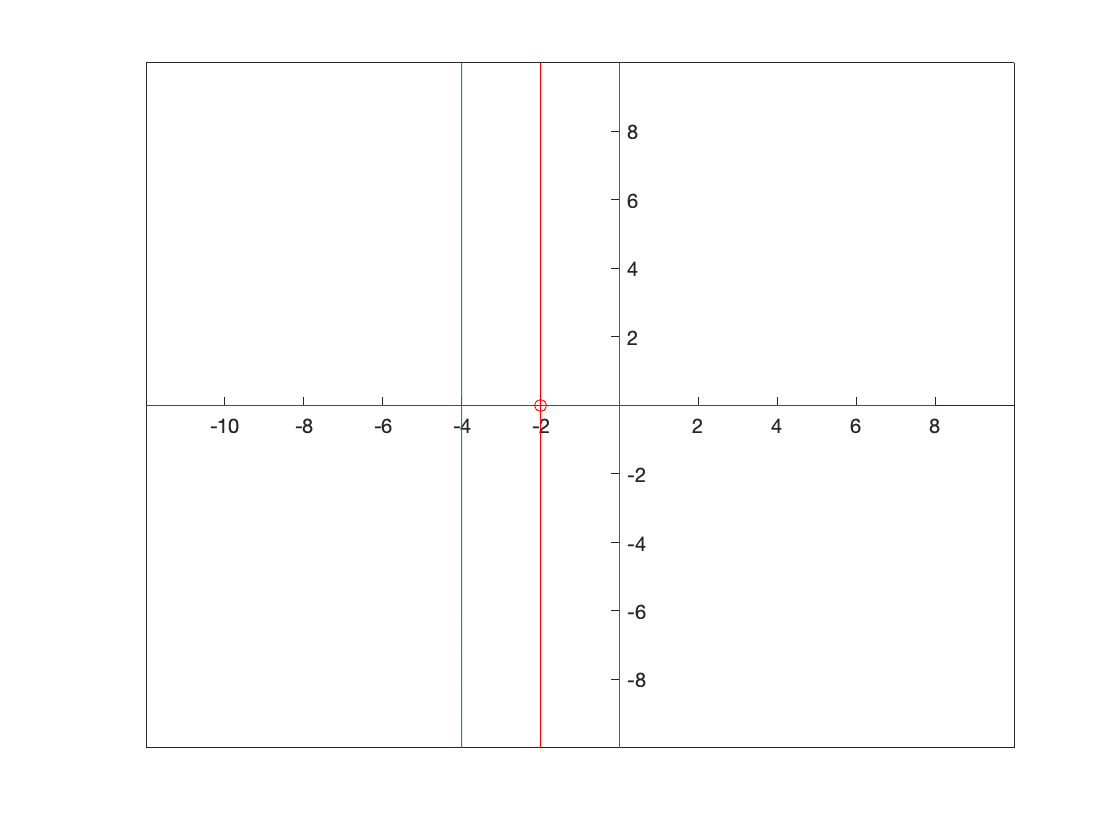

 set(gca, 'XAxisLocation', 'origin')
set(gca, 'YAxisLocation', 'origin')